# Configuración y Simulación de un Modelo de Simulink con Paso Fijo desde MATLAB con Señal de Entrada Proporcionada desde MATLAB

### Abrir el Modelo de Simulink:

- Utiliza `load_system` para cargar el modelo especificado.

### Configurar el Solver y Parámetros de Integración con Paso Fijo:

- Configura el solver '`ode4`' (Runge-Kutta de 4º orden).

- Establece el tipo de paso como fijo.

- Define el tamaño del paso fijo en 0.01 segundos usando `set_param`.

- Ajusta otros parámetros de simulación como el tiempo de simulación, tolerancia relativa y tolerancia absoluta.

### Importar los Datos de Entrada desde MATLAB:

- Genera una señal de entrada senoidal y combínala con los datos de tiempo en una matriz.

- Asigna estos datos al espacio de trabajo de MATLAB.

- Configura el bloque '`From Workspace`' en Simulink para utilizar estos datos.

### Simular el Sistema:

- Ejecuta la simulación del modelo con `sim` y obtiene los resultados.

### Mostrar los Resultados:

- Extrae los datos de salida de la simulación.

- Grafica los resultados utilizando `plot`.

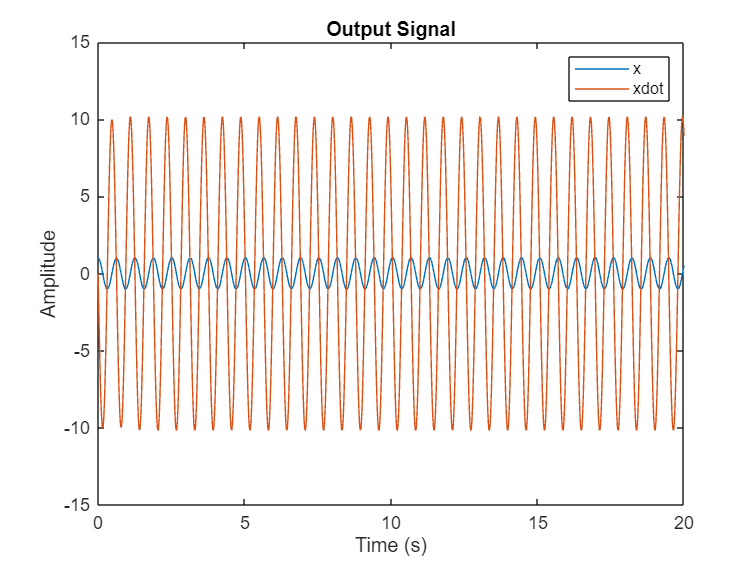

clear all; close all


% Nombre del modelo Simulink
modelName = 't6_recurso3';

% 1. Abrir el modelo de Simulink
load_system(modelName);

% 2. Configurar el solver y parámetros de integración
set_param(modelName, 'Solver', 'ode4','FixedStep', '0.01');  % Establecer el solver en 'ode45'
% set_param(modelName, 'SolverType', 'fixed-step');  % Establecer tipo de paso variable
% set_param(modelName, 'FixedStep', '0.01');  % Establecer tamaño del paso fijo (solo si el tipo de paso es fijo)
% set_param(modelName, 'StopTime', '20');  % Establecer tiempo de simulación en 20 segundos
% set_param(modelName, 'RelTol', '1e-6');  % Establecer tolerancia relativa
% set_param(modelName, 'AbsTol', '1e-6');  % Establecer tolerancia absoluta

% 3. Importar los datos de entrada desde MATLAB
% Crear datos de entrada (ejemplo)
t = (0:0.01:20)'; % Tiempo de 0 a 10 segundos con paso de 0.01 segundos
step_time = 1; % Time at which the step occurs

% Step signal
u = t >= step_time;

inputData = [t, u]; % Combinar tiempo y datos en una matriz

% Asignar los datos al espacio de trabajo
assignin('base', 'inputData', inputData);

% Configurar el bloque 'From Workspace' para usar los datos importados
%inputBlockPath = [modelName, '/Input']; % Ruta del bloque 'From Workspace'
%set_param(inputBlockPath, 'VariableName', 'inputData');

% 4. Simular el sistema
% Parámetros del modelo:
wn = 10;
xi = 0;

simOut = sim(modelName);

% Mostrar resultados
outputSignal = simOut.get('xout');
plot(simOut.tout, outputSignal);
legend('x','xdot')
title('Output Signal');
xlabel('Time (s)');
ylabel('Amplitude');


% Cerrar el modelo sin guardar cambios
%close_system(modelName, 0);



